## Allan Variance Calculation for Angular Velocity in X axis

The Allan variance is calculated as follows:

Log *L* stationary gyroscope samples with a sample period $\tau_{0}$. Let  $\Omega$ be the logged samples. 

imu = readtable('imu.csv');

omega = imu.IMU_angular_velocity_z;
Fs = 40;
t0 = 1/Fs;

For each sample, calculate the output angle $\theta$:


$$\theta(t) = \int^{t}\Omega(t')dt'$$


For discrete samples, the cumulative sum multiplied by $\tau_{0}$ can be used.

theta = cumsum(omega, 1)*t0;

Next, calculate the Allan variance:


$$\sigma^2(\tau) =
\frac{1}{2\tau^2}<(\theta_{k+2m}-2\theta_{k+m}+\theta_{k})^2>$$


where $\tau = m\tau_{0}$ and $<>$ is the ensemble average. 

The ensemble average can be expanded to:


$$\sigma^2(\tau) =
\frac{1}{2\tau^2(L-2m)}\sum_{k=1}^{L-2m}(\theta_{k+2m} - 2\theta_{k+m}
+ \theta_{k})^2$$


maxNumM = 100;
L = size(theta, 1);
maxM = 2.^floor(log2(L/2)); 
m = logspace(log10(1), log10(maxM), maxNumM).';
m = ceil(m); % m must be an integer.
m = unique(m); % Remove duplicates.

tau = m*t0;

avar_ang_z = zeros(numel(m), 1);
for i = 1:numel(m)
    mi = m(i);
    avar_ang_z(i,:) = sum( ...
        (theta(1+2*mi:L) - 2*theta(1+mi:L-mi) + theta(1:L-2*mi)).^2, 1);
end
avar_ang_z = avar_ang_z ./ (2*tau.^2 .* (L - 2*m));

Finally, the Allan deviation $\sigma(t) = \sqrt{\sigma^2(t)}$ is used to determine the gyroscope noise parameters. 

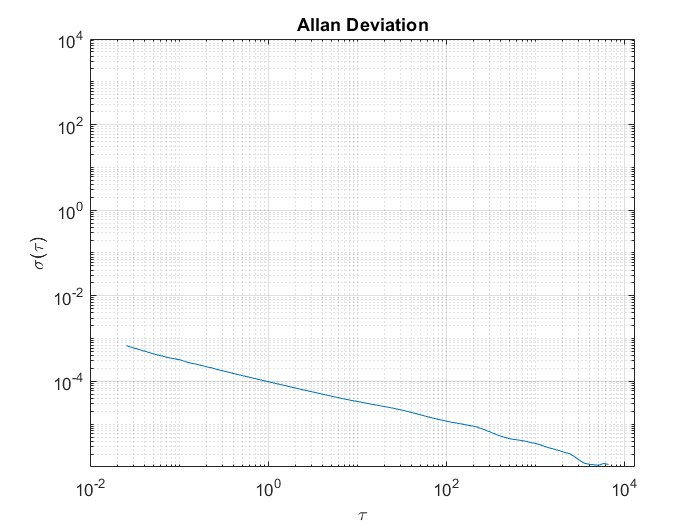

adev = sqrt(avar_ang_z);

figure
loglog(tau, adev)
title('Allan Deviation')
xlabel('\tau');
ylabel('\sigma(\tau)')
grid on
axis equal

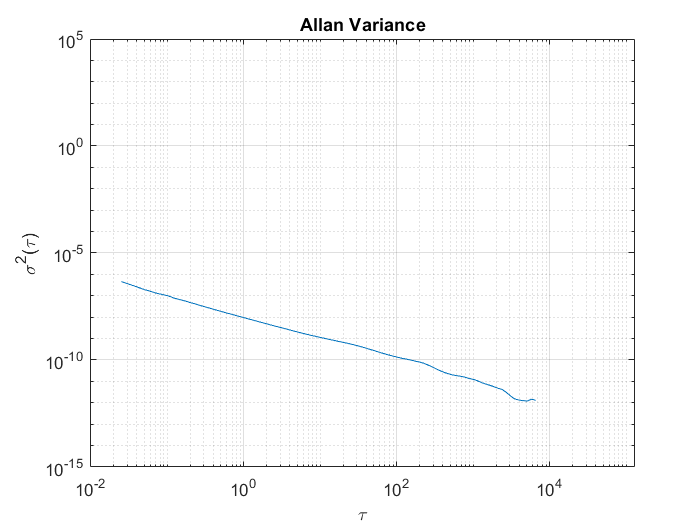

figure
loglog(tau, avar_ang_z)
title('Allan Variance')
xlabel('\tau');
ylabel('\sigma^2(\tau)')
grid on
axis equal

## Angle Random Walk

The angle random walk is characterized by the white noise spectrum of the gyroscope output. The PSD is represented by: 


$$S_\Omega(f) = N^2$$


where

*N* = angle random walk coefficient

Substituting into the original PSD equation and performing integration yields:


$$\sigma^2(\tau) = \frac{N^2}{\tau}$$


The above equation is a line with a slope of -1/2 when plotted on a log-log plot of $\sigma(\tau)$ versus $\tau$. The value of *N* can be read directly off of this line at $\tau = 1$.

% Find the index where the slope of the log-scaled Allan deviation is equal
% to the slope specified.
slope = -0.5;
logtau = log10(tau);
logadev = log10(adev);
dlogadev = diff(logadev) ./ diff(logtau);
[~, i] = min(abs(dlogadev - slope));

% Find the y-intercept of the line.
b = logadev(i) - slope*logtau(i);

% Determine the angle random walk coefficient from the line.
logN = slope*log(1) + b;
N = 10^logN

N = 9.6923e-05

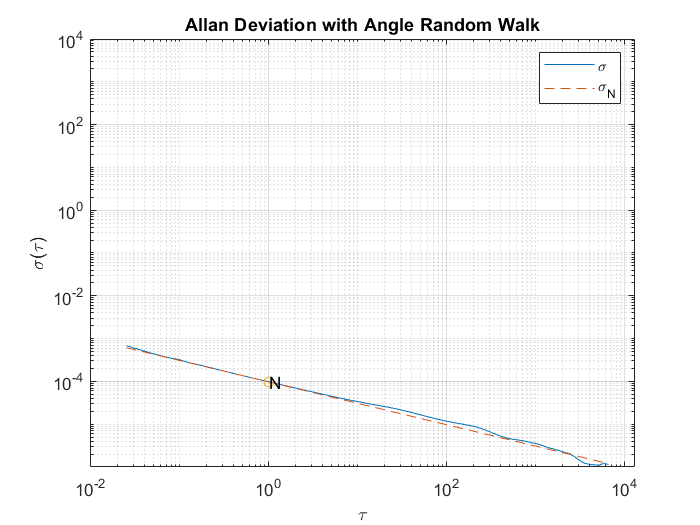


% Plot the results.
tauN = 1;
lineN = N ./ sqrt(tau);
figure
loglog(tau, adev, tau, lineN, '--', tauN, N, 'o')
title('Allan Deviation with Angle Random Walk')
xlabel('\tau')
ylabel('\sigma(\tau)')
legend('\sigma', '\sigma_N')
text(tauN, N, 'N')
grid on
axis equal

## Rate Random Walk

The rate random walk is characterized by the red noise (Brownian noise) spectrum of the gyroscope output. The PSD is represented by:


$$S_\Omega(f) = (\frac{K}{2\pi})^2\frac{1}{f^2}$$


where

*K* = rate random walk coefficient

Substituting into the original PSD equation and performing integration yields:


$$\sigma^2(\tau) = \frac{K^2\tau}{3}$$


The above equation is a line with a slope of 1/2 when plotted on a log-log plot of $\sigma(\tau)$ versus $\tau$. The value of *K* can be read directly off of this line at $\tau = 3$.

% Find the index where the slope of the log-scaled Allan deviation is equal
% to the slope specified.
slope = 0.5;
logtau = log10(tau);
logadev = log10(adev);
dlogadev = diff(logadev) ./ diff(logtau);
[~, i] = min(abs(dlogadev - slope));

% Find the y-intercept of the line.
b = logadev(i) - slope*logtau(i);

% Determine the rate random walk coefficient from the line.
logK = slope*log10(3) + b;
K = 10^logK

K = 2.6654e-08

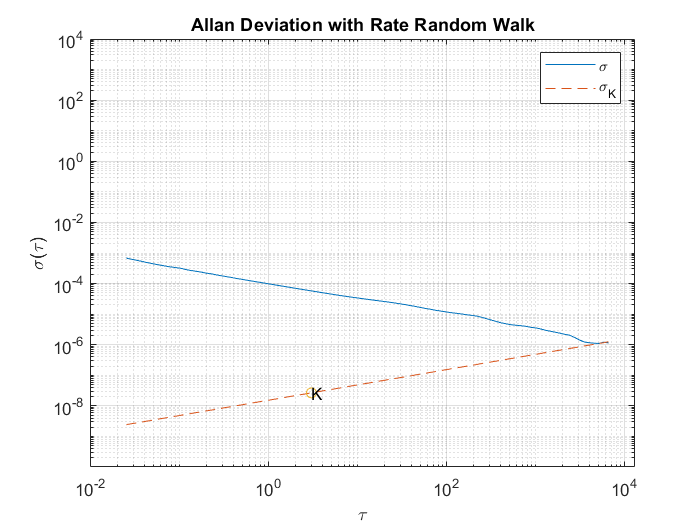


% Plot the results.
tauK = 3;
lineK = K .* sqrt(tau/3);
figure
loglog(tau, adev, tau, lineK, '--', tauK, K, 'o')
title('Allan Deviation with Rate Random Walk')
xlabel('\tau')
ylabel('\sigma(\tau)')
legend('\sigma', '\sigma_K')
text(tauK, K, 'K')
grid on
axis equal

## Bias Instability

The bias instability is characterized by the pink noise (flicker noise) spectrum of the gyroscope output. The PSD is represented by:


$$S_{\Omega}(f) = \left\{\begin{array}{lr}(\frac{B^2}{2\pi})\frac{1}{f} 
& : f \leq f_0\\0 & : f > f_0\end{array}\right.$$


where

*B* = bias instability coefficient

$f_0$ = cut-off frequency

Substituting into the original PSD equation and performing integration yields:


$$\sigma^2(\tau) = \frac{2B^2}{\pi}[\ln{2} + \\
-\frac{sin^3x}{2x^2}(sinx + 4xcosx) + Ci(2x) - Ci(4x)]$$


where


$$x = \pi f_0\tau$$


*Ci* = cosine-integral function

When $\tau$ is much longer than the inverse of the cutoff frequency, the PSD equation is:


$$\sigma^2(\tau) = \frac{2B^2}{\pi}\ln{2}$$


The above equation is a line with a slope of 0 when plotted on a log-log plot of $\sigma(\tau)$ versus $\tau$. The value of *B* can be read directly off of this line with a scaling of $\sqrt{\frac{2\ln{2}}{\pi}} \approx 0.664$.

% Find the index where the slope of the log-scaled Allan deviation is equal
% to the slope specified.
slope = 0;
logtau = log10(tau);
logadev = log10(adev);
dlogadev = diff(logadev) ./ diff(logtau);
[~, i] = min(abs(dlogadev - slope));

% Find the y-intercept of the line.
b = logadev(i) - slope*logtau(i);

% Determine the bias instability coefficient from the line.
scfB = sqrt(2*log(2)/pi);
logB = b - log10(scfB);
B = 10^logB

B = 1.6926e-06

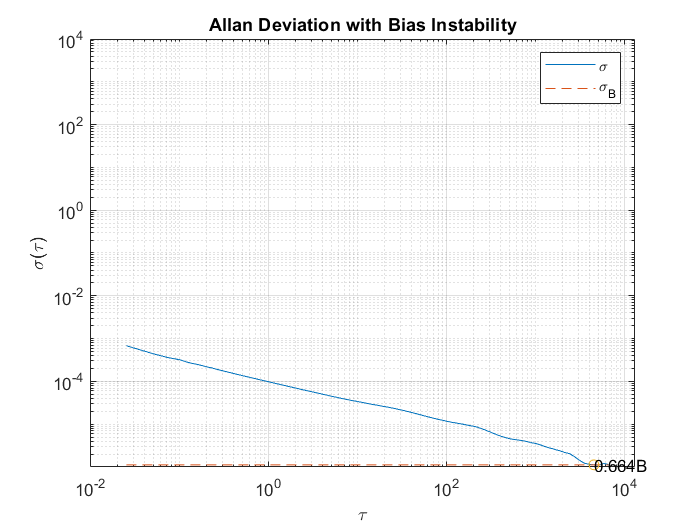


% Plot the results.
tauB = tau(i);
lineB = B * scfB * ones(size(tau));
figure
loglog(tau, adev, tau, lineB, '--', tauB, scfB*B, 'o')
title('Allan Deviation with Bias Instability')
xlabel('\tau')
ylabel('\sigma(\tau)')
legend('\sigma', '\sigma_B')
text(tauB, scfB*B, '0.664B')
grid on
axis equal

Now that all the noise parameters have been calculated, plot the Allan deviation with all of the lines used for quantifying the parameters.

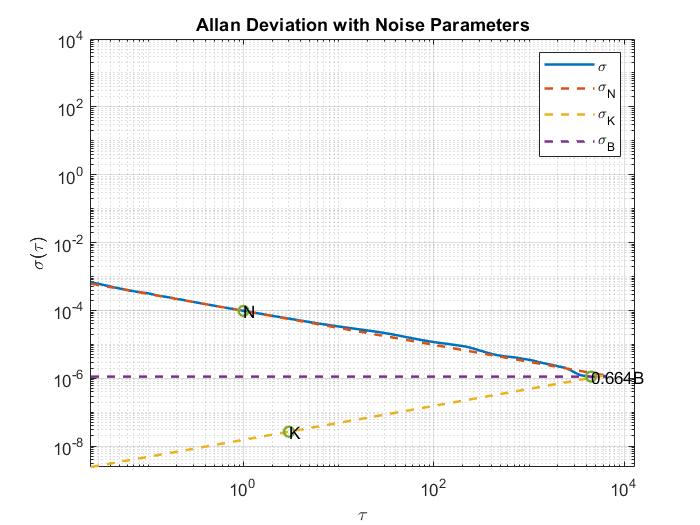

tauParams = [tauN, tauK, tauB];
params = [N, K, scfB*B];
figure
loglog(tau, adev, tau, [lineN, lineK, lineB], '--', ...
    tauParams, params, 'o',"LineWidth",1.5)
title('Allan Deviation with Noise Parameters')
xlabel('\tau')
ylabel('\sigma(\tau)')
legend('\sigma', '\sigma_N', '\sigma_K', '\sigma_B')
text(tauParams, params, {'N', 'K', '0.664B'})
grid on
axis equal

xlim([0 12689])
ylim([0 10000])

## References

- IEEE Std. 647-2006 IEEE Standard Specification Format Guide and Test Procedure for Single-Axis Laser Gyros

*Copyright 2018 The MathWorks, Inc.*